% make sure we have a clean environment
clear

d =  [6e-06 -1.7e-05 4e-06 -4e-06 0 1.9e-05 -5e-06 5e-06]';

% Construct system matrix for the ray path models
s2=sqrt(2);
G = [1,0,0,1,0,0,1,0,0;
     0,1,0,0,1,0,0,1,0;
     0,0,1,0,0,1,0,0,1;
     1,1,1,0,0,0,0,0,0;
     0,0,0,1,1,1,0,0,0;
     0,0,0,0,0,0,1,1,1;
     s2,0,0,0,s2,0,0,0,s2;
     0,0,0,0,0,0,0,0,s2];

% Get the singular values for the system matrix
[U,S,V] = svd(G);


### 3.a) i) Use the generalized inverse of G, with the compact SVD decomposition.

% Find dimensions of G
[m,n]=size(G);

%disp('System rank:')
p=rank(G);

Gdagger = V(:,1:p)*inv(S(1:p,1:p))*U(:,1:p)';

%Estimates
model_parameters_1 = Gdagger*d

model_parameters_1 = 	1.0e+-5 *

   -0.0369
   -0.8697
    0.1399
    0.0303
   -0.6702
    0.2732
    0.9732
    0.2066
    0.3536


model_parameters_11 = pinv(G, 4.8e-15)*d;

### ii) Use available software, e.g. the backslash operator in MATLAB.

model_parameters_2 = G\d

model_parameters_2 = 	1.0e+-4 *

   -0.0070
   -0.0696
         0
   -0.0143
   -0.0637
    0.0413
    0.1180
         0
    0.0354


### Plot the model parameters from 3(a)i

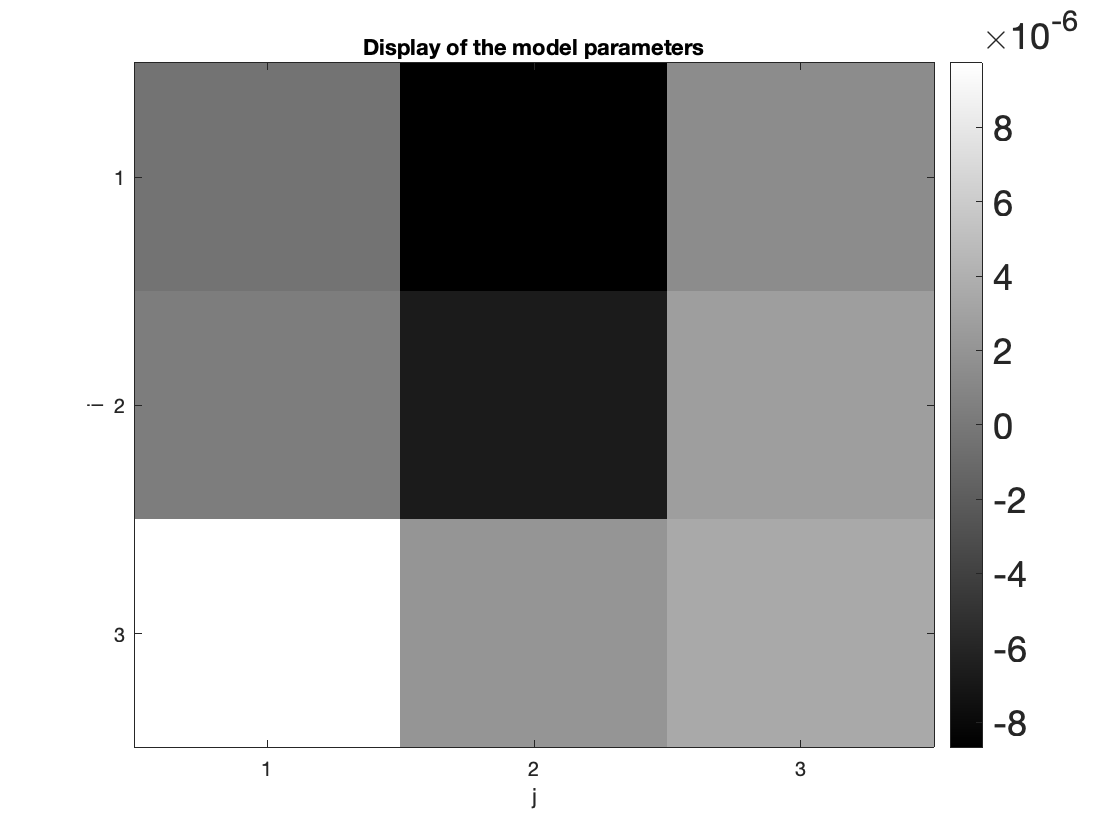

figure(7)
clf
colormap('gray')
imagesc(reshape(model_parameters_1,3,3)');
%caxis([-0.9e-5 1e-5])
set(colorbar,'Fontsize',18);
set(gca,'xtick',[1,2,3]);
set(gca,'ytick',[1,2,3]);
xlabel('j')
ylabel('i')
title('Display of the model parameters')

### Plot the model parameters from 3(a)ii

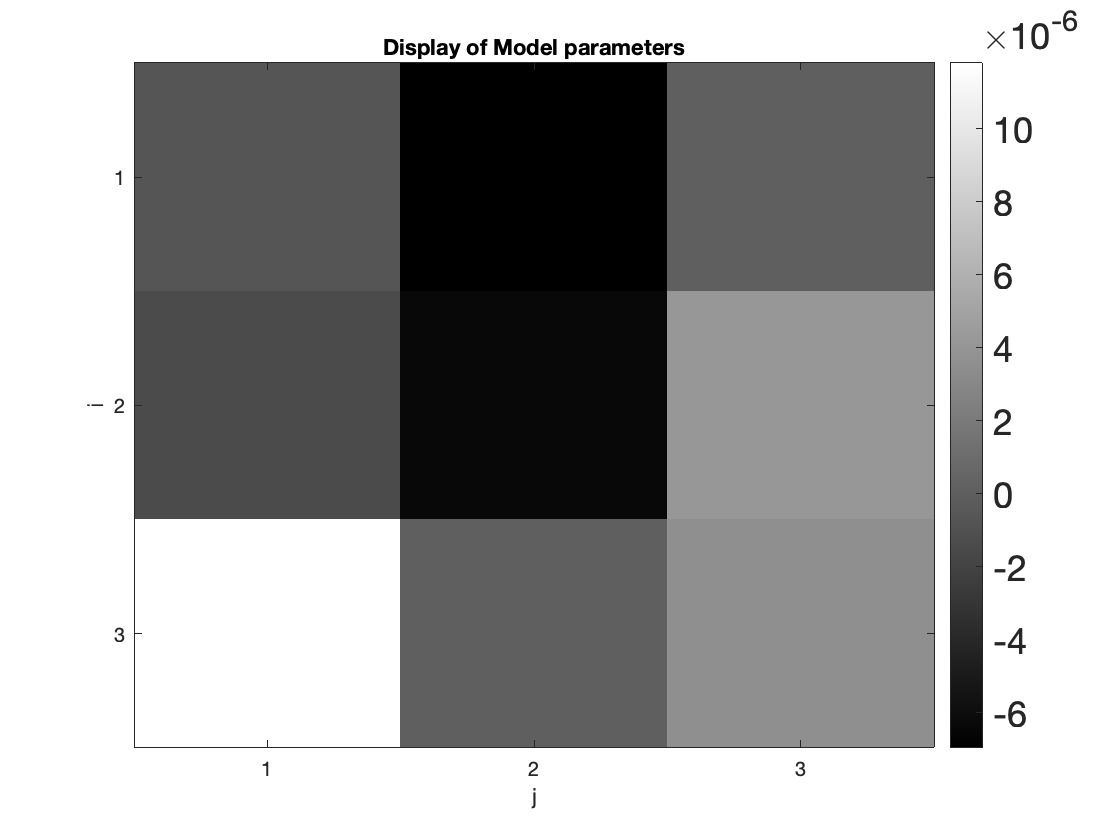

figure(8)
clf
colormap('gray')
imagesc(reshape(model_parameters_2,3,3)');
%caxis([-0.1e-4 0.2e-4])
set(colorbar,'Fontsize',18);
set(gca,'xtick',[1,2,3]);
set(gca,'ytick',[1,2,3]);
xlabel('j')
ylabel('i')
title('Display of Model parameters')

### Discuss the difference between estimates in 3(a)i and 3(a)ii

The estimates in 3(a) i, are to the order of $10^{-5}$ while those in 3(a)ii, are to the order of $10^{-4}$.

### Use each set of model parameter estimates to predict data. 

d_dagger = G*model_parameters_1 %using model parameter_1

d_dagger = 	1.0e+-4 *

    0.0967
   -0.1333
    0.0767
   -0.0767
   -0.0367
    0.1533
   -0.0500
    0.0500


d_back_slash = G*model_parameters_2 %using model parameter_2 

d_back_slash = 	1.0e+-4 *

    0.0967
   -0.1333
    0.0767
   -0.0767
   -0.0367
    0.1533
   -0.0500
    0.0500


### Compare both sets of predicted data to each other, and to the actual data.

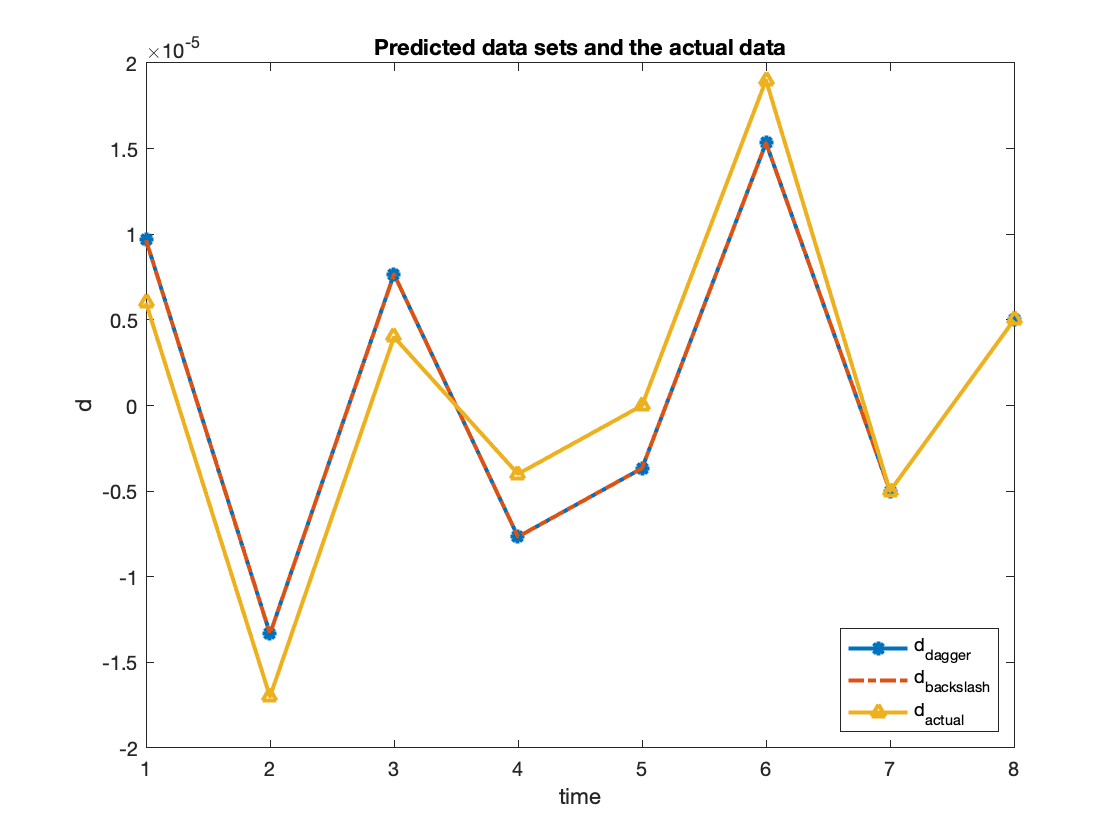

figure(10)
plot(d_dagger,'-*','LineWidth', 2)
hold on
plot(d_back_slash,'-.','LineWidth', 2)
hold on
plot(d,'-^','LineWidth', 2)
legend('d_{dagger}','d_{backslash}','d_{actual}','Location','southeast')
title('Predicted data sets and the actual data')
xlabel('time'); ylabel('d');

Both sets of predicted data are the same basing to the graph compared tot the actual data.

### b) Determine the dimension of the data null space. 

dim_data_Null_space = m-p 

dim_data_Null_space = 1

### Plot the vectors in the data null space.

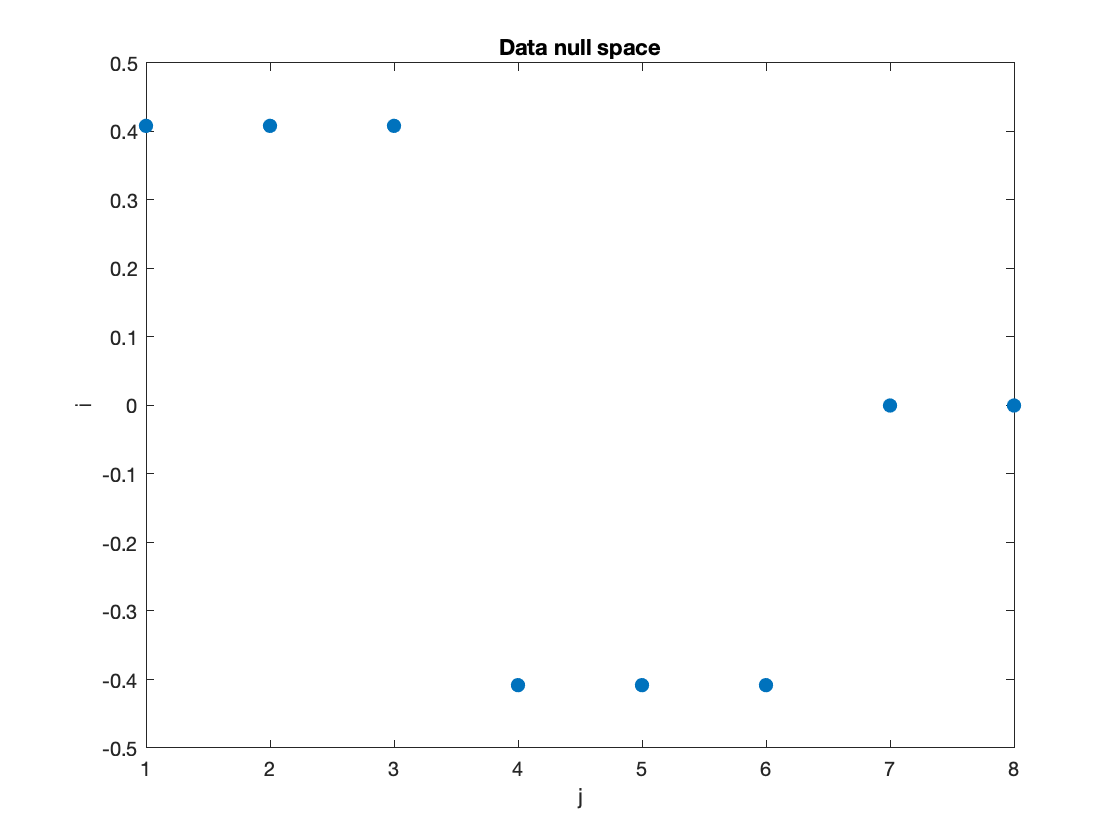

figure(9)
plot(U(:,8),'.','MarkerSize',20)
title('Data null space')
xlabel('j')
ylabel('i')

### c) Determine the dimension of the model null space. 

dim_model_Null_space = 2

dim_model_Null_space = 2

### Plot the vectors in the model null space on 3×3 grids, as they are illustrated in Figure 3.2.

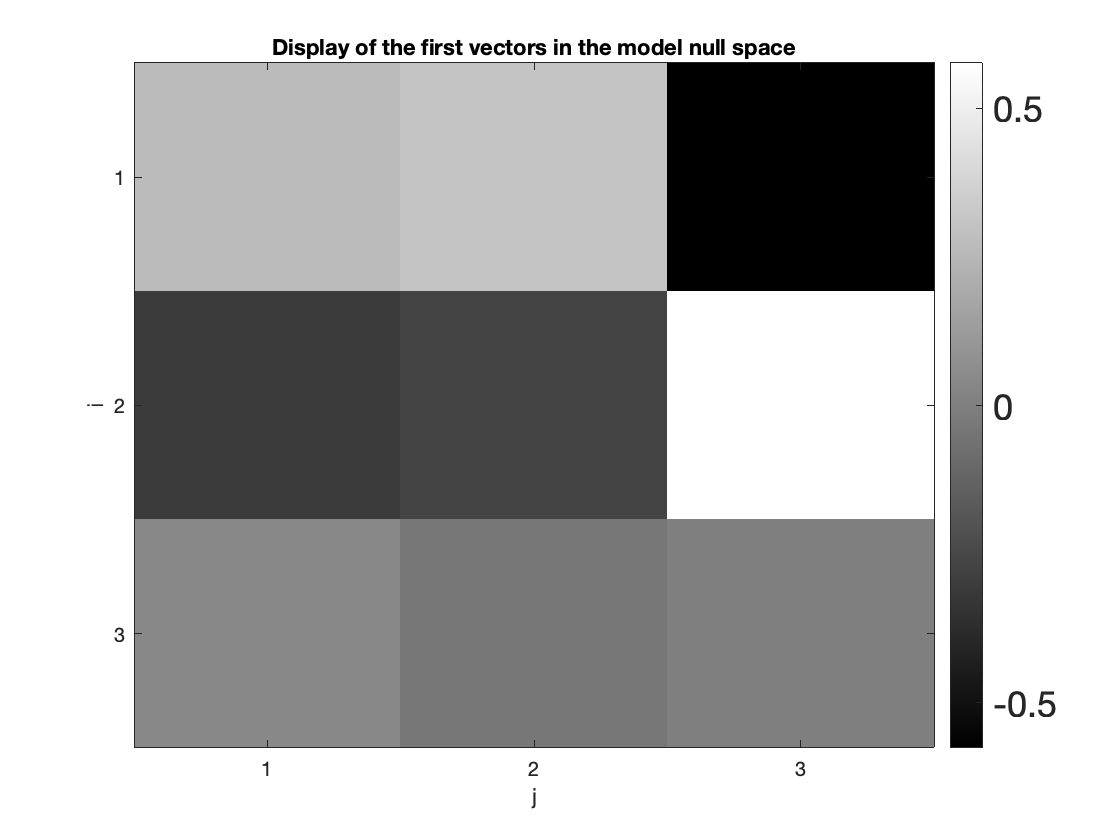

m01=reshape(V(:,p+1),3,3)';
m02=reshape(V(:,p+2),3,3)';

figure(1)
clf
colormap('gray')
imagesc(m01)
%caxis([-0.6 0.6]);
set(colorbar,'Fontsize',18);
set(gca,'xtick',[1,2,3]);
set(gca,'ytick',[1,2,3]);
xlabel('j')
ylabel('i')
title('Display of the first vectors in the model null space');

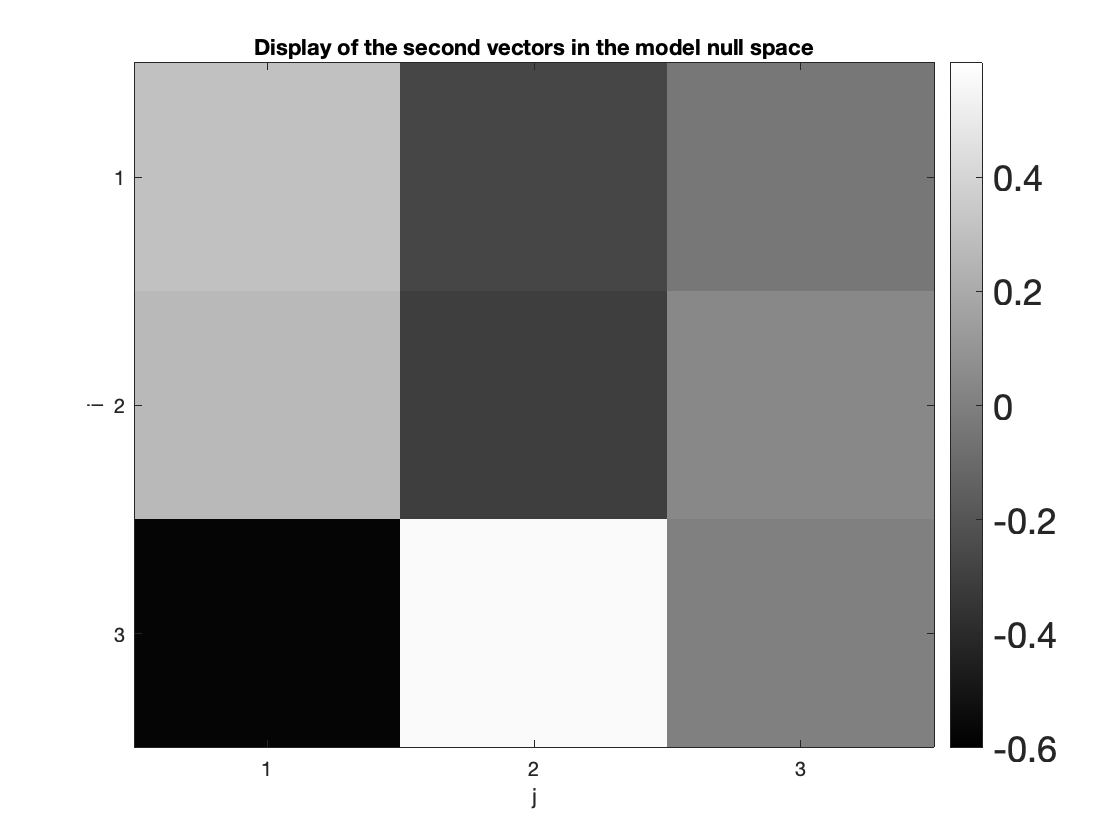

figure(2)
clf
colormap('gray')
imagesc(m02)
caxis([-0.6 0.6]);
set(colorbar,'Fontsize',18);
set(gca,'xtick',[1,2,3]);
set(gca,'ytick',[1,2,3]);
xlabel('j')
ylabel('i')
title('Display of the second vectors in the model null space');

### (d) Is it possible to have two sets of parameters that produce the same data? Explain why or why not, and give an example if possible.

Yes, since all the model parameters are in the model null space, hence any model parameter obtained as aresult of the linear combination of the elements in the model null space  set plus  any model parameter will always yield the same fitted data. see for instance, example 3.a) i and 3.a) ii. and also in the calculation below, the value of the fitted data is  the same for different linear combinations of  model null space vectors.

M1 = model_parameters_1 + 6*V(:,8) + 5*V(:,9); 
d1 = G*M1

d1 = 	1.0e+-4 *

    0.0967
   -0.1333
    0.0767
   -0.0767
   -0.0367
    0.1533
   -0.0500
    0.0500


M2 = model_parameters_2 + 0.6*V(:,8) + 0.9*V(:,9); 
d2 = G*M2

d2 = 	1.0e+-4 *

    0.0967
   -0.1333
    0.0767
   -0.0767
   -0.0367
    0.1533
   -0.0500
    0.0500


### (e) Is it possible to have two sets of data that produce the same model parameters? Explain why or why not, and give an example if possible.

Yes, Since our data exists in the the data null space, hence any two sets of data produced as aresult of a linear combination of elements in the data null space plus any data will yeild the same model parameters. see for instance, the example below in the calculation gives the same model parameters for two different linear combinations.

d1 = d_dagger + 6*U(:,8);
M1 = G\d1

M1 = 	1.0e+-4 *

   -0.0070
   -0.0696
         0
   -0.0143
   -0.0637
    0.0413
    0.1180
         0
    0.0354


d2 = d_back_slash + 0.9*U(:,8);
M2 = G\d2

M2 = 	1.0e+-4 *

   -0.0070
   -0.0696
         0
   -0.0143
   -0.0637
    0.0413
    0.1180
         0
    0.0354
